# Enterprise sizes by NAICS in Canada Report

## Importing and Data Processing

(We are importing our data after raw data processing in MS Excel.)

advTech = importfile4("advtech.csv");
advTech.totalSize = advTech.AgricultureForestryFishingAndHunting + advTech.MiningQuarryingAndOilAndGasExtraction + advTech.Utilities + advTech.Construction + advTech.Manufacturing + advTech.WholesaleTrade + advTech.RetailTrade + advTech.TransportationAndWarehousing + advTech.PostalServicesCouriersAndMessengersWarehousingAndStorage7 + advTech.InformationAndCulturalIndustries + advTech.FinanceAndInsuranceExcludingMonetaryAuthorities8;
advTech.Properties.VariableNames{1} = 'Technology'

advTech = 7×17 table
                           Technology                            AgricultureForestryFishingAndHunting    MiningQuarryingAndOilAndGasExtraction    Utilities    Construction    Manufacturing    WholesaleTrade    RetailTrade    TransportationAndWarehousing    PostalServicesCouriersAndMessengersWarehousingAndStorage7    InformationAndCulturalIndustries    FinanceAndInsuranceExcludingMonetaryAuthorities8    RealEstateAndRentalAndLeasing    ProfessionalScientificAndTechnicalServices    ManagementOfCompaniesAndEnterprises    AdministrativeAndSupportWasteManagementAndRemediationServices    totalSize
    _________________________________________________________    _

emergingTech = importfile4("emertech.csv");
emergingTech.totalSize = emergingTech.AgricultureForestryFishingAndHunting + emergingTech.MiningQuarryingAndOilAndGasExtraction + emergingTech.Utilities + emergingTech.Construction + emergingTech.Manufacturing + emergingTech.WholesaleTrade + emergingTech.RetailTrade + emergingTech.TransportationAndWarehousing + emergingTech.PostalServicesCouriersAndMessengersWarehousingAndStorage7 + emergingTech.InformationAndCulturalIndustries + emergingTech.FinanceAndInsuranceExcludingMonetaryAuthorities8;
emergingTech.Properties.VariableNames{1} = 'Technology'

emergingTech = 7×17 table
                    Technology                     AgricultureForestryFishingAndHunting    MiningQuarryingAndOilAndGasExtraction    Utilities    Construction    Manufacturing    WholesaleTrade    RetailTrade    TransportationAndWarehousing    PostalServicesCouriersAndMessengersWarehousingAndStorage7    InformationAndCulturalIndustries    FinanceAndInsuranceExcludingMonetaryAuthorities8    RealEstateAndRentalAndLeasing    ProfessionalScientificAndTechnicalServices    ManagementOfCompaniesAndEnterprises    AdministrativeAndSupportWasteManagementAndRemediationServices    totalSize
    ___________________________________________    ________________________

contributionsByTech = importfile11("biggerTechContributions2.csv")

contributionsByTech = 3×2 table
             Techs              PercentageContribution
    ________________________    ______________________

    Advanced technology use                2          
    Emerging technology use                3          
    Traditional technologies              95          


contributionsByInd = importfile8("biggerIndContributions3.csv")

contributionsByInd = 6×2 table
                               Industries                                PercentageContribution
    _________________________________________________________________    ______________________

    Postal services, couriers and messengers, warehousing and storage               7          
    Finance and insurance excluding monetary authorities                            8          
    Total selected services                                                         5          
    All transportation                                                              6          
    Total all surveyed industries                                                   4          
    others                                                                         70          


distribution = importfile12("distribution.csv");
distribution.IndustryCode = categorical(["CATEGORY 1";"CATEGORY 2"; "CATEGORY 3";"CATEGORY 4";"CATEGORY 5";"CATEGORY 6";"CATEGORY 7";"CATEGORY 8";"CATEGORY 9";"CATEGORY 10";"CATEGORY 11";"CATEGORY 12";"CATEGORY 13";"CATEGORY 14";"CATEGORY 15"])

distribution = 15×4 table
                                 Industries                                  AdvancedTechnologyUse    EmergingTechnologyUse    IndustryCode
    _____________________________________________________________________    _____________________    _____________________    ____________

    Agriculture, forestry, fishing and hunting                                       37.6                     22.3             CATEGORY 1  
    Mining, quarrying, and oil and gas extraction                                    39.2                     21.8             CATEGORY 2  
    Utilities                                                                        67.3                     36.7             CATEGORY 3  
    Construction                                                                     36.3                     19.9             CATEGORY 4

## Visualizations

### Pie Chart of 

### *the Technologies* used in Industries

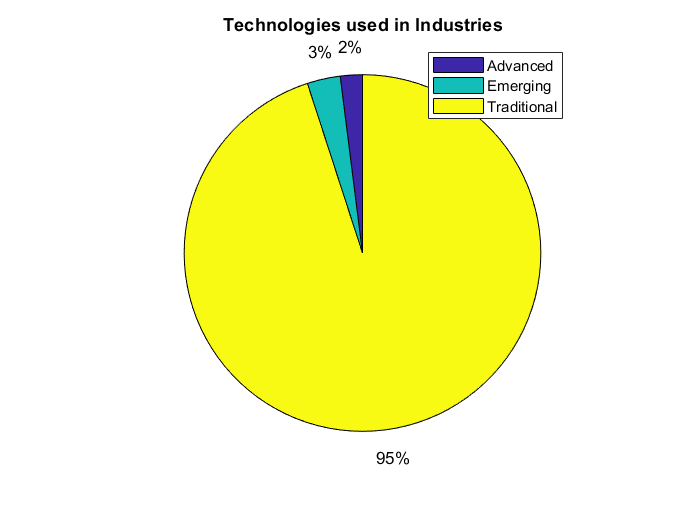

pie(contributionsByTech.PercentageContribution)
legend('Advanced','Emerging','Traditional')
title('Technologies used in Industries')

Contribution of *Advanced* and *Emerging* technologies in industries is still very less but *considerably visible*.

### Pie Chart of 

### *Industry* Classifications

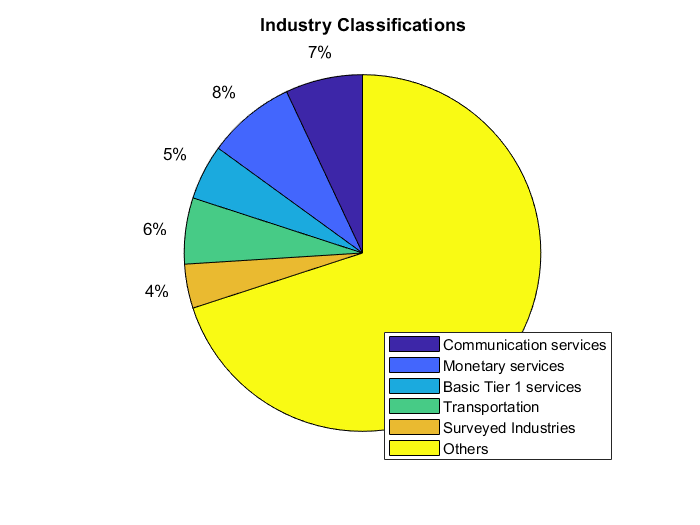

pie(contributionsByInd.PercentageContribution)
legend('Communication services','Monetary services','Basic Tier 1 services','Transportation','Surveyed Industries','Others','Location',"best")
title('Industry Classifications')

These five sectors have a fair hold in the stream of multi sector enterprices with max being in the *finance* sector.

### Bar Chart of 

### *Emerging Technology* types and their hold of influence in Application

or: Which is the maximum applied Emerging Technology?

This chart gives us an idea about what all are the Emerging Technologies and which technology is currently in maximum use or minimum use.

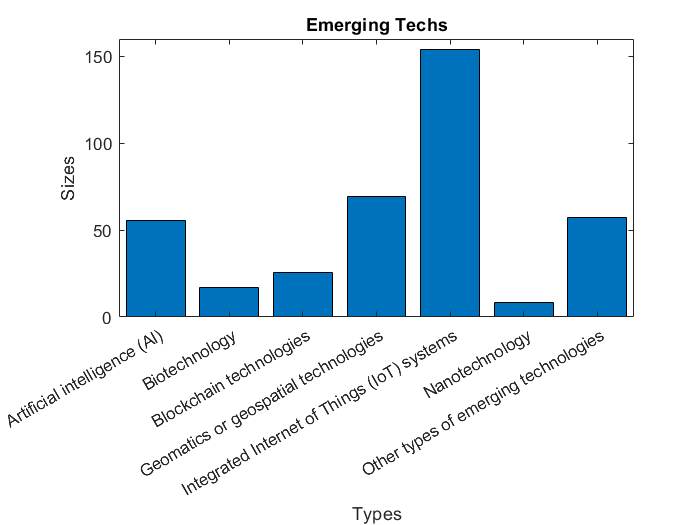

bar(emergingTech.Technology,emergingTech.totalSize,'DisplayName','emergingTech.totalSize')
title('Emerging Techs')
xlabel('Types')
ylabel('Sizes')

We see that in the emerging technologies* IoT sytems *has maximum influence followed by *Geomantics* and *AI*.

### Bar Chart of 

### *Advanced Technology* types and their hold of influence in Application

or: Which is the maximum applied Advanced Technology?

This chart gives us an idea about what all technologies come under Advanced Technologies and which technology is currently in maximum use or minimum use.

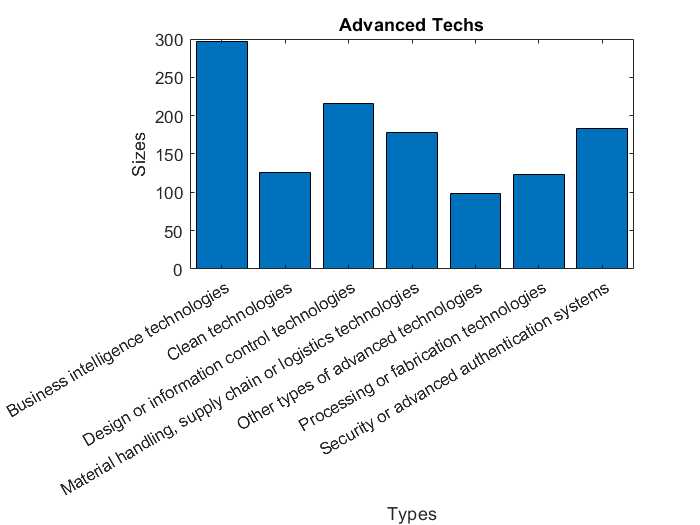

bar(advTech.Technology,advTech.totalSize,'DisplayName','advTech.totalSize')
title('Advanced Techs')
xlabel('Types')
ylabel('Sizes')

We see in this chart that in the advanced technologies* Business Intelligence Tech *has maximum influence followed by *IT*.

### Bar Chart of 

### *Advanced Tech use distribution* in Industries 

or: Which Industry is in lead in using the Advanced technologies?

This chart would give us an idea about the use of Advanced technologies overall in industries. (We had to plot by the industry codes as the names were too big! A reference is attached later for ease.)

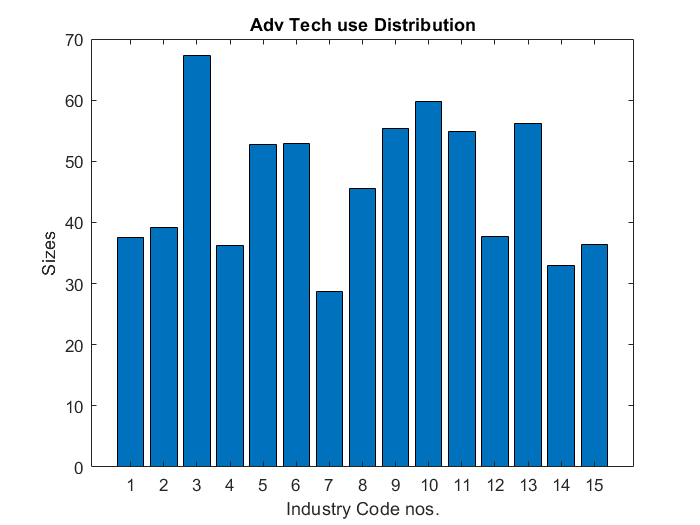

bar(distribution.AdvancedTechnologyUse)
%bar(distribution.IndustryCode,distribution.AdvancedTechnologyUse,'DisplayName','distribution.AdvancedTechnologyUse')
title('Adv Tech use Distribution')
xlabel('Industry Code nos.')
ylabel('Sizes')

Hence we see that category 3 has the highest use i.e., the *Utilities* sector. With categories 10 and 13 having fairly high shares following utilities.

For reference here is the list:

indCodeTable = table(distribution.Industries)

indCodeTable = 15×1 table
                                    Var1                                 
    _____________________________________________________________________

    Agriculture, forestry, fishing and hunting                           
    Mining, quarrying, and oil and gas extraction                        
    Utilities                                                            
    Construction                                                         
    Manufacturing                                                        
    Wholesale trade                                                      
    Retail trade                                                         
    Transportation and warehousing                                       
    Postal services, couriers and messengers, warehousing and storage 7  
    Information and cultural industries                                  
    Finance and insurance excluding monetary author

### Bar Chart of 

### *Emerging Tech use distribution* in Industries 

or: Which Industry is in lead of using the Emerging Technologies?

Similarly, this chart would give us an idea about which industries use how much of the available emerging technologies. (Please refer the Industry codes table for ease.)

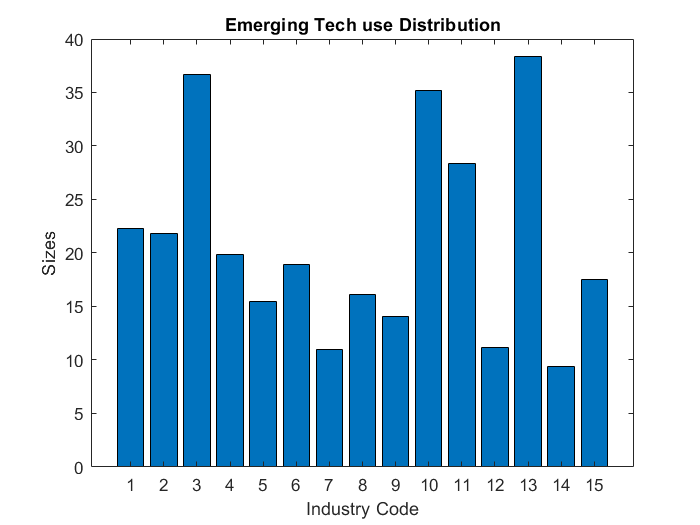

bar(distribution.EmergingTechnologyUse)
title('Emerging Tech use Distribution')
xlabel('Industry Code')
ylabel('Sizes')

Hence here we see that Category 13 i.e., the Professional, Scientific and the Technical services lead in using the Emerging Technologies.

For reference here is the list:

indCodeTable = table(distribution.Industries)

indCodeTable = 15×1 table
                                    Var1                                 
    _____________________________________________________________________

    Agriculture, forestry, fishing and hunting                           
    Mining, quarrying, and oil and gas extraction                        
    Utilities                                                            
    Construction                                                         
    Manufacturing                                                        
    Wholesale trade                                                      
    Retail trade                                                         
    Transportation and warehousing                                       
    Postal services, couriers and messengers, warehousing and storage 7  
    Information and cultural industries                                  
    Finance and insurance excluding monetary author

## Inferences and Verifications

Now that we have answers to questions like:  

**What are the bigger Industry sectors?  ***Finance > Communication > Transportation > Tier 1 services  > Industries. ***What are the contribution pecentages of Advanced and Emerging Tech in overall Tech use? ***2% and 3% respectively. ***Which particular Advanced or Emerging Tech is used the most? ***Business Intelligence and IoT Systems respectively. ***Which Industry uses the most of Advanced or Emerging Tech? ***Utilities sector and Professional, Scientific and the Technical services sector respectively.*

We can further focus on Utilities sector , the Professional, Scientific and the Technical services sector, the Business Intelligence Tech and the IoT Systems Tech.

Let's draw out the information of Business Intelligence Systems and IoT systems.

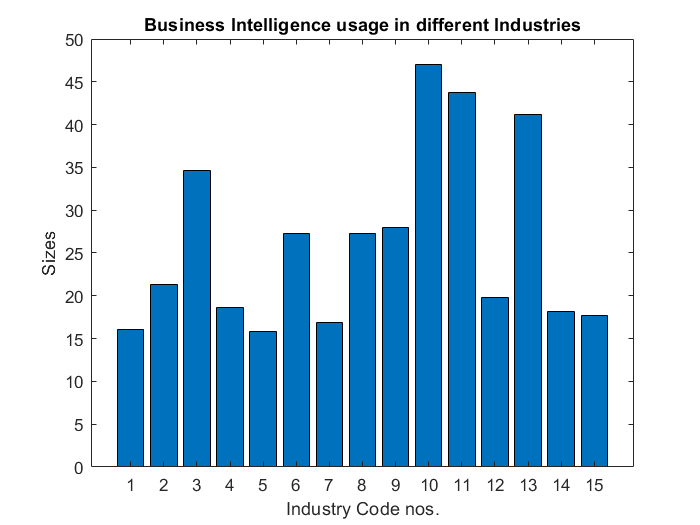

businessIntelligence = advTech(advTech.Technology == 'Business intelligence technologies',:);
businessIntelligence = table2cell(businessIntelligence);
businessIntelligence = transpose(businessIntelligence);
bar(cell2mat(businessIntelligence(2:16,1)))
xlabel('Industry Code nos.')
ylabel('Sizes')
title('Business Intelligence usage in different Industries')

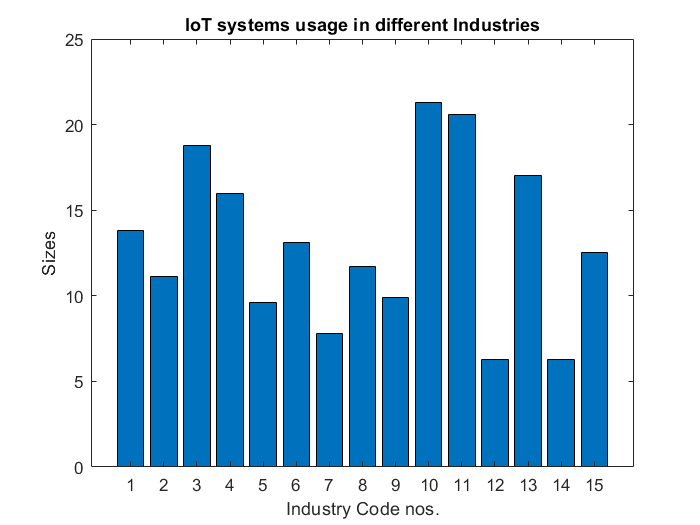

IoTsys = emergingTech(emergingTech.Technology == 'Integrated Internet of Things (IoT) systems',:);
IoTsys = table2cell(IoTsys);
IoTsys = transpose(IoTsys);
bar(cell2mat(IoTsys(2:16,1)))
xlabel('Industry Code nos.')
ylabel('Sizes')
title('IoT systems usage in different Industries')

From the above graphs we can say that Business Intelligence and IoT systems Technology both are used the most in *Information and Cultural Industries* (CATEGORY 10). 

Also we can note that *Utilities*, i.e., CATEGORY 3 has a fair share of usage with *size 34.6 with the highest being size 47* (in Information and Cultural Industries obviously) in the Advanced Tech usage of Business Intelligence. Now, in IoT systems usage also we can note that *Professional, Scientific and the Technical services* sector CATEGORY 13 has a fairly high usage *size i.e., 17 with the highest in it being size 21.3*. So here our past inferences seem to match the evidences!

Let's represent these information in pie chart now:

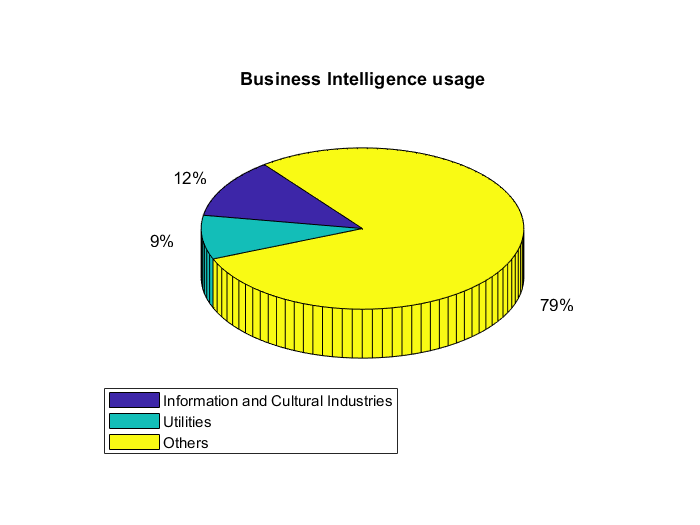

ab = (cell2mat(businessIntelligence(2:16,1)));
c = ab(10,1); d = ab(3,1); e = sum([transpose(ab(1:2)),transpose(ab(4:9)),transpose(ab(11:15))]);
pie3([c,d,e])
legend('Information and Cultural Industries','Utilities','Others','Location',"southwest")
title('Business Intelligence usage')

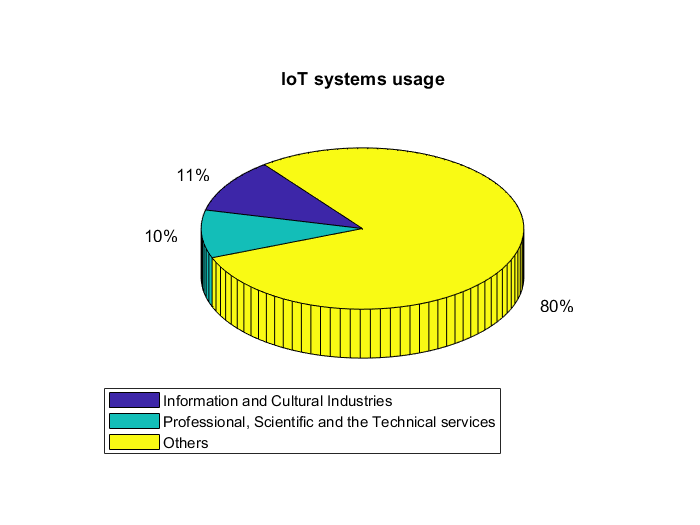

fg = (cell2mat(IoTsys(2:16,1)));
h = fg(10,1); i = fg(3,1); j = sum([transpose(fg(1:2)),transpose(fg(4:9)),transpose(fg(11:15))]);
pie3([h,i,j])
legend('Information and Cultural Industries','Professional, Scientific and the Technical services','Others','Location',"southwest")
title('IoT systems usage')

And here again we can see our past inferences match the evidences from the plots.

## Conclusions

**What are the bigger Industry sectors?  ***Finance > Communication > Transportation > Tier 1 services  > Industries. ***What are the contribution pecentages of Advanced and Emerging Tech in overall Tech use? ***2% and 3% respectively. ***Which particular Advanced or Emerging Tech is used the most? ***Business Intelligence and IoT Systems respectively. ***Which Industry uses the most of Advanced or Emerging Tech? ***Utilities sector and Professional, Scientific and the Technical services sector respectively.*

Yes indeed they were correct.* And additionally we conclude that,*

*Business Intelligence *(Advanced Tech) and *IoT systems* (Emerging Tech) both are used the most in ***Information and Cultural Industries***, with a respective size of 47 and 21.3. Which is quite a logical outcome! And Industries like *Utilities* and *Professional, Scientific and the Technical services *also have a fair contribution to the usage of these two Techs being the most to use the Advanced and Emerging Techs respectively.

*Hence it is seen that the newest of the technologies have started to come into use visibly in the surveyed industries of Canada but have nowhere yet replaced the traditional methods. There is still a lot of area to be covered and conquered by the newest of the Techs.*

## Thank You!